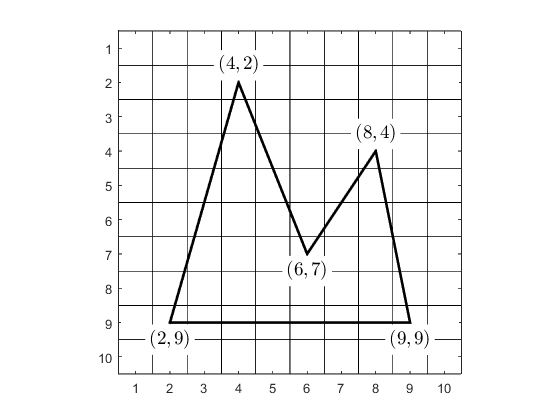

clear

% Raster parameters
Nx = 10;
Ny = 10;

% Polygon vertices and colour
X = [0.1, 0.8, 0.7, 0.5, 0.3];
Y = [0.2, 0.2, 0.7, 0.4, 0.8];
colour = [210, 210, 255];

% Initialise raster array and calculate pixel co-ordinates
img = 255 * uint8(ones(Ny, Nx, 3));
[X, Y] = pixelcoordinates(X, Y, Nx, Ny);

% Plot initial raster
plotraster(img)
hold on
fill(X, Y, 'w', LineWidth=2, FaceAlpha=0)
hold off
text(X(1), Y(1)+0.5, '$(2,9)$', FontSize=14, Interpreter='latex', BackgroundColor='w', HorizontalAlignment='center')
text(X(2), Y(2)+0.5, '$(9,9)$', FontSize=14, Interpreter='latex', BackgroundColor='w', HorizontalAlignment='center')
text(X(3), Y(3)-0.5, '$(8,4)$', FontSize=14, Interpreter='latex', BackgroundColor='w', HorizontalAlignment='center')
text(X(4), Y(4)+0.5, '$(6,7)$', FontSize=14, Interpreter='latex', BackgroundColor='w', HorizontalAlignment='center')
text(X(5), Y(5)-0.5, '$(4,2)$', FontSize=14, Interpreter='latex', BackgroundColor='w', HorizontalAlignment='center')

exportgraphics(gcf,'../images/scanline_example_1.png','Resolution',300) 

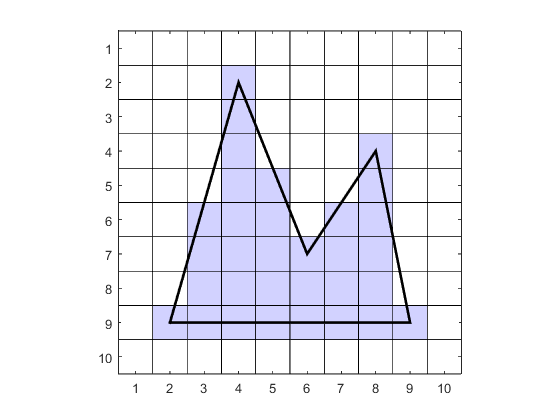



% Draw polygon
img = drawpolygon(img, X, Y, colour);

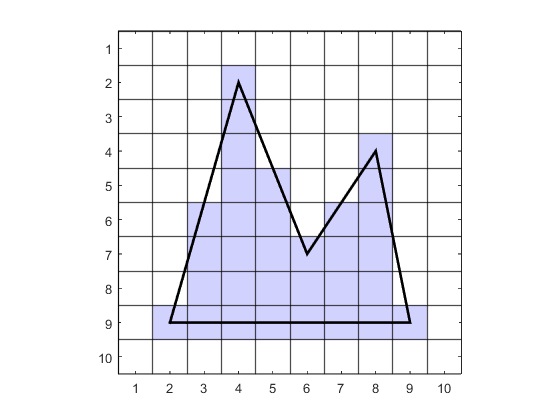


image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1);
    yline(row-0.5, Color='k', LineWidth=1);
end
fill(X, Y, 'w', LineWidth=2, FaceAlpha=0)
hold off

xticks(1:10)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])

function [X, Y] = pixelcoordinates(X, Y, Nx, Ny)

X = 1 + floor(X * Nx);
Y = 1 + floor((1 - Y) * Ny);

end

function R = drawpolygon(R, X, Y, colour)

% Generate edge table
n = length(X);
ET = [];
j = n;
for i = 1 : n
    if Y(i) < Y(j)
        imin = i; 
        imax = j;
    elseif Y(i) > Y(j)
        imin = j;
        imax = i;
    else
        j = i;
        continue
    end

    dx = abs(X(imin) - X(imax));
    dy = abs(Y(imin) - Y(imax));
    xstep = sign(X(imax) - X(imin));
    N = 0;

    ET = [ET ; X(imin), N, xstep, dx, dy, Y(imin), Y(imax)];
    j = i;
end

% Loop through scanlines
y = min(Y);
AET = [];
n = 1;
while isempty(ET) == 0 || isempty(AET) == 0

    % Move edges from ET to AET whose ymin = y
    i = 1;
    while i <= size(ET, 1)
        if ET(i,6) == y
            AET = [AET ; ET(i,:)];
            ET(i,:) = [];
        else
            i = i + 1;
        end
    end

    % Sort AET by x value
    AET = sortrows(AET);

    % Fill scanline
    for i = 1 : 2 : size(AET, 1)
        for x = AET(i,1) : AET(i+1,1)
            R(y, x, :) = colour;
        end
    end

    % Update AET
    i = 1;
    while i <= size(AET, 1)
        % Remove edges from AET whose ymax = y
        if AET(i,7) == y
            AET(i,:) = [];
            continue
        end

        % Update N and x
        AET(i,2) = AET(i,2) + AET(i,4);
        while AET(i,2) >= AET(i,5)
            AET(i,1) = AET(i,1) + AET(i,3);
            AET(i,2) = AET(i,2) - AET(i,5);
        end
        i = i + 1;
    end

    % Move to next scanline
    y = y + 1;

    plotraster(R)
    hold on
    fill(X, Y, 'w', LineWidth=2, FaceAlpha=0)
    hold off
    n = n + 1;
    filename = sprintf('../images/scanline_example_%1i.png', n);
    exportgraphics(gcf,filename,'Resolution',300) 

end

end

function plotraster(img)

[Ny, Nx, ~] = size(img);

image(img)
hold on
for row = 1 : 1 : Nx
    plot([row-0.5, row-0.5], [0, Ny+0.5], Color='k', LineWidth=0.5)
    plot([0, Nx+0.5], [row-0.5, row-0.5], Color='k', LineWidth=0.5)
end
hold off

xticks(1:1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])

end